This script is based on the example IV.B - Region of Attraction Estimation in the paper "Quasiconvex Sum-of-Squares Programming" y Seiler and Balas (2010)

## Problem Definition

We consider the dynamical system of the *Van der Pol oscillator*:


$$\dot{\;x} =f\left(x\right)=\left\lbrack \begin{array}{c}
-x_2 \\
x_1 +\left(x_1^2 -1\right)x_2 
\end{array}\right\rbrack$$


let us plot this as a vector field:

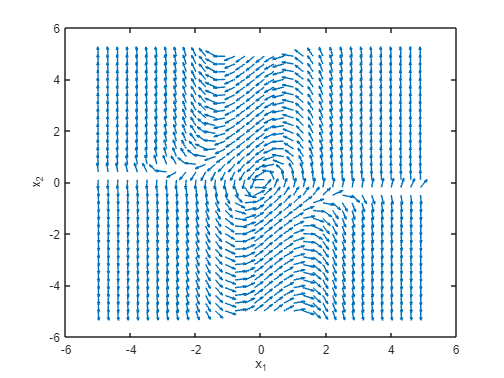

x_range = -5:0.3:5;
y_range = -5:0.3:5;
[X, Y] = meshgrid(x_range, y_range);

% system
dX = -Y;
dY = X + (X.^2 - ones(size(X))) .* Y;
% Normalize the arrows (better visualization)
dX_norm = dX ./ sqrt(dX.^2 + dY.^2);
dY_norm = dY ./ sqrt(dX.^2 + dY.^2);

% plot
figure;
quiver(X, Y, dX_norm, dY_norm)
xlabel('x_1')
ylabel('x_2')

it can be shown that the system around a certain region of$x=0$ is stable using the Lyapunov candidate $V(x) = x^T P x$ with 


$$P=\left\lbrack \begin{array}{cc}
1\ldotp 5 & -0\ldotp 5\\
-0\ldotp 5 & 1\ldotp 0
\end{array}\right\rbrack$$


To do that, let us use Casos. We define a state vector $x = [x_1, x_2]^T$ as a so so called **indeterminate variable **of dim $(2, 1)$:

% define states
x = casos.PS('x', 2, 1)

x =   [ x_1]
  [ x_2]
 

Indeterminate variables are not decision variables, which means they represent $x$ in the polynomial $p(x)$. We will not minimize for $x$.

We also define the nonlinear function/system dynamics $f$ using the variable $x$:

% system equation
f = [-x(2);
    x(1)+ ( x(1)^2 - 1 ) * x(2)];

Now we can define the square matrix $P$:

P = [1.5, -0.5;
    -0.5, 1.0]

P =     1.5000   -0.5000
   -0.5000    1.0000


and obtain the Lyapunov candidate with:

V = x'*P*x

V =   1.5*x_1^2 - x_1*x_2 + x_2^2
 

as we can see, $V$ is now a polynomial.

To verify local asymptotic stability, we need the linearized system matrix $A$:

A = [0, -1;
    1, -1]

A =      0    -1
     1    -1


and we calculate the time derivative $\dot{V} = \nabla V  f(x)$ for the linear system $f(x) = Ax$

Vdot_lin = nabla(V, x) * A*x

Vdot_lin =   -x_1^2 - x_2^2
 

obviously, $-x_1^2 -x_2^2 \leq 0$ $\forall x \in \mathbb{R}^n$.

## Region of Attraction

### Define SOS problem

Now we want to analyze the actual (nonlinear system) to find a region around $x=0$ with asymptotic stability. 

We start by calculating $\dot{V}$ for the nonlinear case:

Vdot = nabla(V, x)*f

Vdot =   -x_1^2 - x_2^2 - x_1^3*x_2 + 2*x_1^2*x_2^2
 

Now we define a polynomial $s(x,u) \in \Sigma [x]$ using the gram matrix functionality by Casos:

z = monomials(x, 1:2)

z =   [     x_1]
  [     x_2]
  [   x_1^2]
  [ x_1*x_2]
  [   x_2^2]
 

s = casos.PS.sym('s', z, 'gram')

s =   (s_0)*x_1^2 + (s_1+s_5)*x_1*x_2 + (s_6)*x_2^2 + (s_2+s_10)*x_1^3 
  + (((s_3+s_7)+s_11)+s_15)*x_1^2*x_2 + (((s_4+s_8)+s_16)+s_20)*x_1*x_2^2 
  + (s_9+s_21)*x_2^3 + (s_12)*x_1^4 + (s_13+s_17)*x_1^3*x_2 + ((s_14+s_18)
  +s_22)*x_1^2*x_2^2 + (s_19+s_23)*x_1*x_2^3 + (s_24)*x_2^4
 

this polynomial now holds the decision variables in gram matrix form. These are the variables for our optimization together with the bilinear decision variable $t$:

t = casos.PS.sym('t')

t =   (t)
 

finally, we add the helper function for negativity:

l = 1e-006*x'*x

l =   1e-006*x_1^2 + 1e-006*x_2^2
 

### Solve the Bisection Problem

The bisection problem is:


$$\[
\begin{array}{ll}
\min_{t,u} & t \\
\text{s.t.} & s(x, u) \in \Sigma[x] \\
& ts(x, u) + (V(x)s(x, u) - \nabla V(x, u)f(x) - l(x)) \in \Sigma[x]
\end{array}
\]
$$


In Casos, we have the following problem definition:


$$\[
\begin{array}{ll}
\min & F(\xi, \pi) \\
\text{s.t.} & \gamma_{lb} < G_l(\xi, \pi) < \gamma_{ub}, \\
& G_c(\xi, \pi) \in K_c, \\
& \text{and} \\
& \xi_{lb} < \xi_l < \xi_{ub}, \\
& \xi_c \in K_c,
\end{array}
\]
$$


now we can define the quasiconvex problem:

qcsos = struct( ...
    'x',s, ...
    'f',t, ...
    'g',s*(V+t)-Vdot-l);

**Notes:**

- x: $s(x,u)$ corresponds to $\xi_c \in K_c$, i.e. the decision variables are SOS

- f: $t$ is the bilinear decision variable

- g: is one constraint equation and corresponds to $G_c \in K_c$, i.e. one SOS polynomial

The cone dimensions need to be defined as:

% settings
% states + constraint are SOS cones
opts.Kx.s = 1; opts.Kc.s = 1;
% ignore infeasibility
opts.error_on_fail = false;

now we can solve the problem:

% solve by bisection
S = casos.qcsossol('S','bisection',qcsos,opts);
% evaluate
sol = S();

and we obtain $\gamma = -t$:

gamma = -sol.f

gamma =   2.30408
 

and $s(x)$

sol.x

ans =   0.267672*x_1^2 - 0.103439*x_1*x_2 + 0.238878*x_2^2 + 2.87602e-007*x_1^3 
  + 3.5206e-007*x_1^2*x_2 - 1.20265e-007*x_1*x_2^2 - 1.6924e-007*x_2^3 
  + 0.232267*x_1^4 + 0.0535714*x_1^3*x_2 - 0.0611572*x_1^2*x_2^2 
  - 0.0953551*x_1*x_2^3 + 0.177006*x_2^4
 

## Result

We can now plot the contour line that belongs to $V(x) = \gamma$:

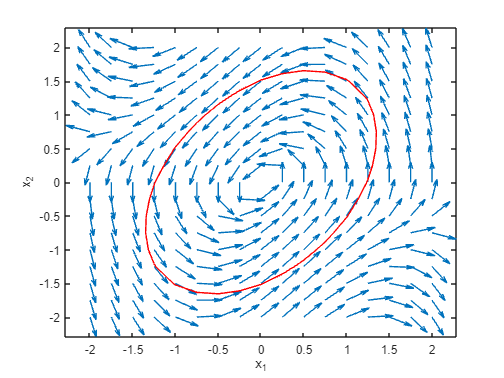

x_range = -2:0.25:2;
y_range = -2:0.25:2;
[X, Y] = meshgrid(x_range, y_range);

% system
dX = -Y;
dY = X + (X.^2 - ones(size(X))) .* Y;
% Normalize the arrows (better visualization)
dX_norm = dX ./ sqrt(dX.^2 + dY.^2);
dY_norm = dY ./ sqrt(dX.^2 + dY.^2);

% plot
figure;
quiver(X, Y, dX_norm, dY_norm)
xlabel('x_1')
ylabel('x_2')
hold on
Z = 1.5.*X.^2 - X.*Y + Y.^2;
contour(X, Y, Z, [double(gamma), double(gamma)], 'r')